% EC_core_to_protected_model
%
% 
%
%
% Copyright (c) 2024 Third Equation LTD.
%
%
%**************************************************************************
% Revision history
% Date      Author
%**************************************************************************
% 15/02/24  veimar.moreno@thirdequation.com
%           First issue.
%**************************************************************************
%                                                                          
%  Modification history of definition file provided for version matching   
%                                                                         
%  Version  Date        Author      Revision Details                            
%  0.0      15/02/24     VM          Initial issue.                             
% *************************************************************************

## Export Simulink Model to Protected Model with FMU Code Generation Capability

In this section, the following steps illustrate how to enable FMU Code Generation capability of a protected model for FMU export. 

FMU export supports protected model code generation with grt and fmu2cs artifacts. Use [*Simulink.ProtectedModel.getSupportedTargets*](https://www.mathworks.com/help/rtw/ref/simulink.protectedmodel.getsupportedtargets.html?s_tid=doc_ta) to get a list of targets that protected model supports.

The following steps use fmu2cs system target file to generate the protected model. 

This script opens model *EC_core_control.slx, *sets system target file to `fmu2cs.tlc`, creates the project data dictionary, sets the models general configuration and exports the model to a protected model, *EC_core_control_protected.slxp*. 

System target file grt.tlc is also supported for this workflow. Compare to grt.tlc, fmu2cs.tlc supports FMU import block code generation, which allow you to export a model with FMU import blocks to a protected model. If the protected model contains artifacts for both system target file, fmu2cs will take effect when exporting standalone FMU. To learn more about protected model code generation, see [explore protected model capabilities](https://www.mathworks.com/help/simulink/slref/protected-models-for-model-reference.html).

% Open model Controller
base_model = "EC_core_control";
open_system(base_model);


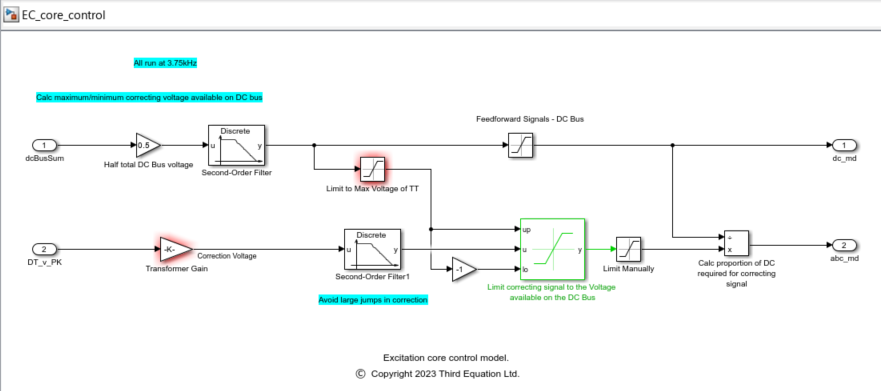

After the model is opened, go to the Save As dialog (Simulation > Save > Save As) and update the **File Name** to EC_core_control_protected. 

% Save model with a different name to avoid warnings when generating the protected model
model = base_model + "_protected";
save_system(base_model, model);

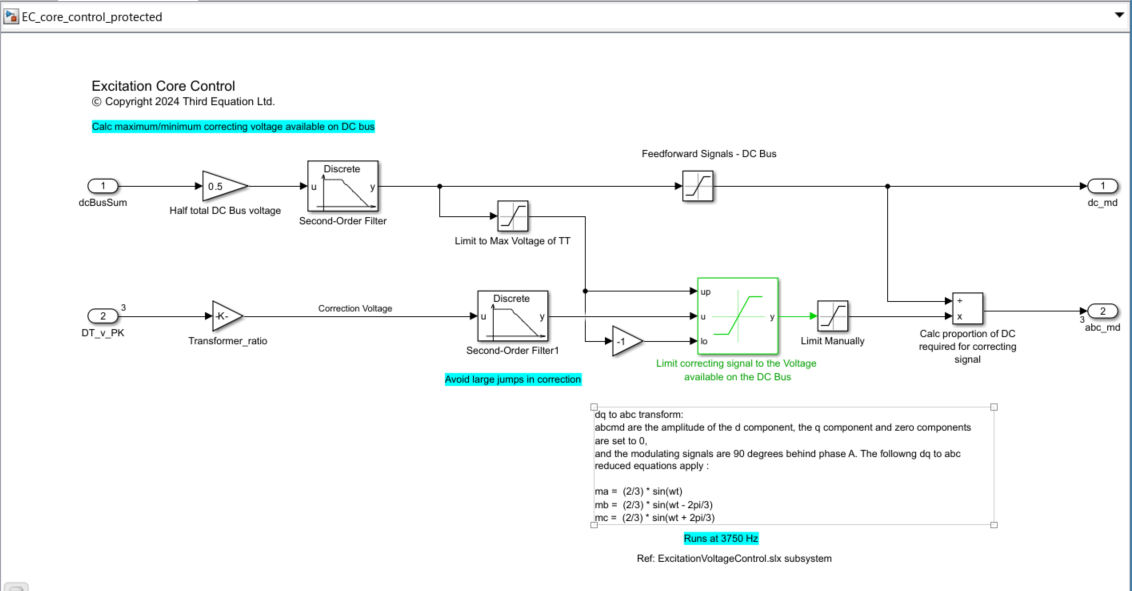

Go to the configuration dialog (Modelling > Model Settings) and update **System target file** to `fmu2cs.tlc` in **Configuration Parameter** > **Code Generation**.

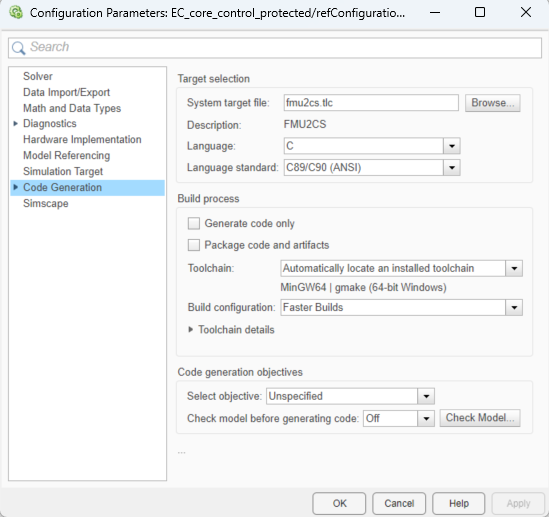

% alternative command-line option to set protected model code generation target to fmu2cs.tlc
% this allows the protected model to be exported as standalone FMU
%set_param(model, 'SystemTargetFile', 'fmu2cs.tlc');
%set_param(model, 'GRTInterface', 'off');
%set_param(model, 'UseToolchainInfoCompliant', 'on');

% to use grt code generation, use command:
% set_param(model, 'SystemTargetFile', 'grt.tlc');

Inconsistent hardware implementation of hardware attributes can result in failure when exporting standalone FMU. To configure these parameters, user can open **Configuration Parameter **> **Hardware Implementation**. Model uses the following setting for code generation:

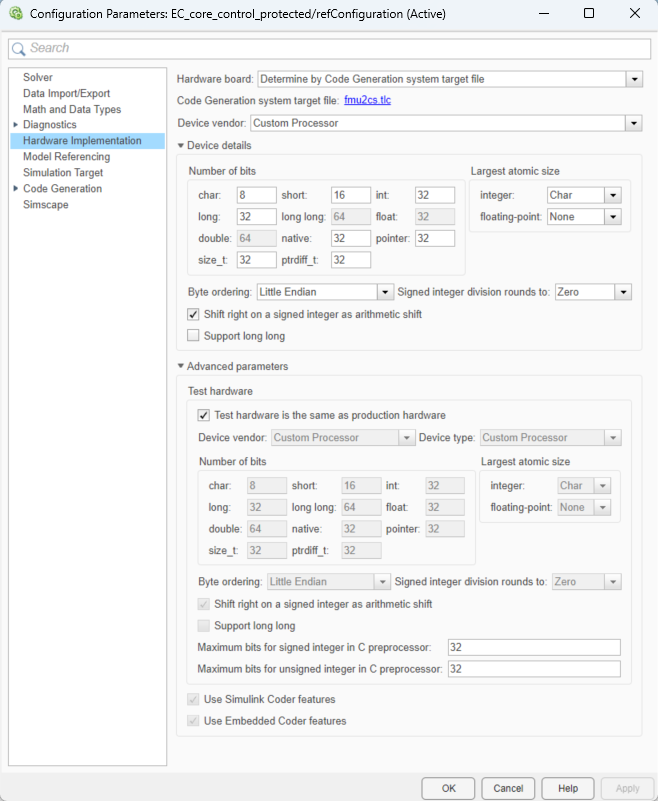

To share a configuration set with multiple models, store it as a *freestanding configuration set* in a Simulink® data dictionary or in the base workspace.

### Create a Simulink data dictionary to store the configuration set

- On the **Modeling** tab, under **Design**, click **Link to Data Dictionary**.

- In the Model Properties dialog box, click **New**. Name the new Simulink data dictionary *fmuGenerationDictionary* and click **Save**.

- Click **OK**.

### **Convert Configuration Set to Configuration Reference**

- Open the Model Explorer.

- In the **Model Hierarchy** pane, expand the top model, EC_core_control. In the list, select the **Configurations** node, and right-click `Configuration (Active)` in the **Contents** pane. In the context menu, select **Convert to Configuration Reference**.

- In the **Name** field, use the name, *ref*`Configuration`. This configuration set object is stored in the data dictionary *fmuGenerationDictionary*`.sldd`*.*

- Click **OK**.

### Include control parameters in the dictionary

Run the core_parameters.m script to add the parameters to the *fmuGenerationDictionary *dictionary.

run('core_parameters.m');

From **Simulation** tab select **Save > Save**

### Generate Protected Model 

From **Simulation** tab select **Save** > **Protected Model**. A dialog box opens where user can select options for creating a protected model.

To enable code generation for standalone FMU export, check **Use Generated Code** and select **Obfuscated source code** in **Content type**. Then select **Protected model (.slp) only** in **Contents**.

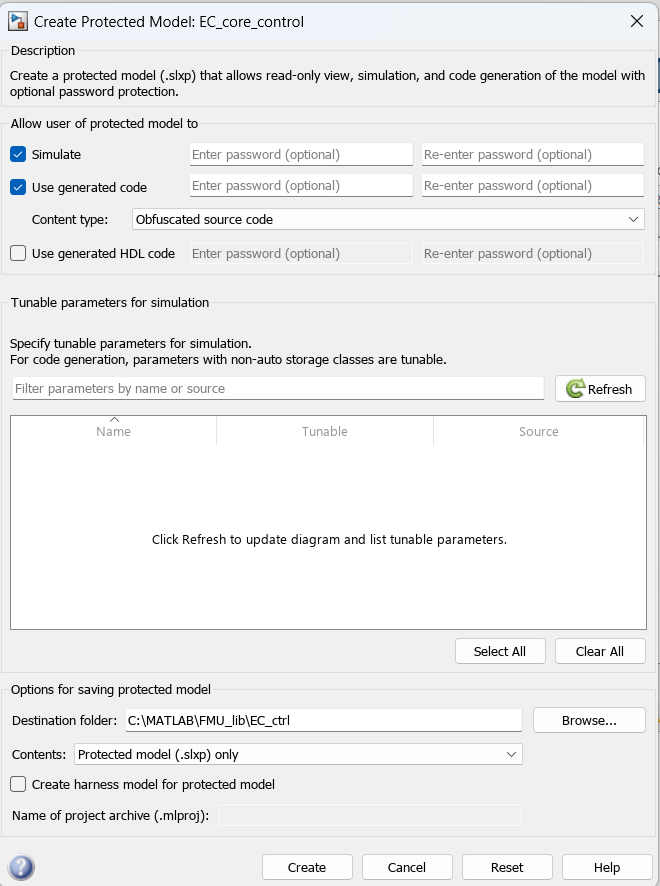

% generate protected model
Simulink.ModelReference.protect(model,'Mode','CodeGeneration','ObfuscateCode',true);

Creating protected model for 'EC_core_control_protected'.
### Starting serial model reference simulation build.


### Successfully updated the model reference simulation target for: EC_core_control_protected
### Starting serial model reference code generation build.
### Checking status of model reference code generation target for model 'EC_core_control_protected'.
### Model reference code generation target (EC_core_control_protected.c) for model EC_core_control_protected is out of date because EC_core_control_protected.c does not exist.
### Setting Hardware Implementation > Device Type to 'MATLAB Host' for model 'EC_core_control_protected'.
### Generating code and artifacts to 'Model specific' folder structure
### Generating code into build folder: C:\Users\Veimar\AppData\Local\Temp\tp84786585_f3cb_45f5_b78d_eac4b594322e\slprj\fmu2cs\EC_core_control_protected


### Invoking Target Language Compiler on EC_core_control_protected.rtw
### Using System Target File: C:\Program Files\MATLAB\R2023b\toolbox\shared\simulink\fmuexport\fmu2cs.tlc
...............................................................................
..........................### Saving binary information cache.
### Using toolchain: MinGW64 | gmake (64-bit Windows)
### Creating 'C:\Users\Veimar\AppData\Local\Temp\tp84786585_f3cb_45f5_b78d_eac4b594322e\slprj\fmu2cs\_sharedutils\rtwshared.mk' ...
### Building 'rtwshared': "$(MINGW_ROOT)\mingw32-make.exe"  -f rtwshared.mk all
 
C:\Users\Veimar\AppData\Local\Temp\tp84786585_f3cb_45f5_b78d_eac4b594322e\slprj\fmu2cs\_sharedutils>call "setup_mingw.bat"  
 
C:\Users\Veimar\AppData\Local\Temp\tp84786585_f3cb_45f5_b78d_eac4b594322e\slprj\fmu2cs\_sharedutils>set "MINGW_ROOT=C:\PROGRA~3\MATLAB\SUPPOR~1\R2023b\3P778C~1.INS\MINGW_~1.INS\bin"  
 
C:\Users\Veimar\AppData\Local\Temp\tp84786585_f3cb_45f5_b78d_eac4b594322e\slprj\fmu2cs\_sharedutils

% close model after protected model is generated
close_system(model);

The* EC_core_control_protected.slxp model* is created.

*Copyright 2023 Third Edquation Ltd.*